## ODE Example

% Example 22.1 
fcn = @(t,y) 4*exp(0.8*t) - 0.5*y;

% exact solution
sol = @(t) 4/1.3*(exp(0.8*t)-exp(-0.5*t)) + 2*exp(-0.5*t);
t = linspace(0,3);
plot(t, sol(t))


### Manual Forward Euler

% obtain solution manually
h = .5; % step size (aka Delta t)
t0 = 0;
y0 = 2; % initial value

% first step (forward euler)
t1 = t0 + h;
y1 = y0 + h*fcn(t0,y0);

% second step (forward euler)
t2 = t1 + h;
y2 = y1 + h*fcn(t1,y1);

% second step (forward euler)
t3 = t2 + h;
y3 = y2 + h*fcn(t2,y2);

ts = [t0, t1, t2, t3];
ys = [y0, y1, y2, y3];

hold on
plot(ts, ys, 'o-')


### Same as above, but in a loop

ts = [t0];
ys = [y0];
while ts(end)<3
    t_prev = ts(end);
    y_prev = ys(end);
    ts(end+1) = t_prev + h;
    ys(end+1) = y_prev + h*fcn(t_prev,y_prev);
end

plot(ts, ys, 'x-')

h = h / 4;
ts = [t0];
ys = [y0];
while ts(end)<3
    t_prev = ts(end);
    y_prev = ys(end);
    ts(end+1) = t_prev + h;
    ys(end+1) = y_prev + h*fcn(t_prev,y_prev);
end

plot(ts, ys, '+-')

### Use MATLAB built-in ODE45

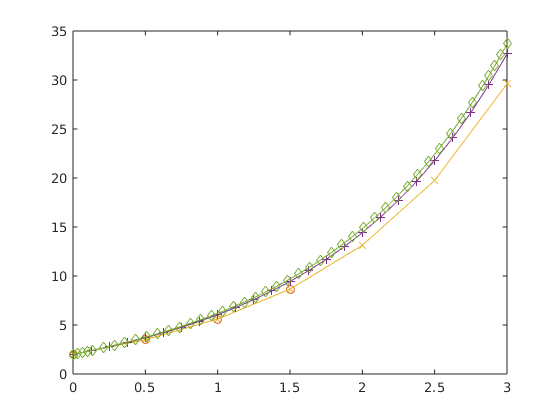

[ts, ys] = ode45(fcn,[t0, 3],y0);

plot(ts, ys, 'd-')

## Lotke-Volterra Equation (predator-prey)

lotke_volterra = @(y,a,b,c,d) [a*y(1)-b*y(1)*y(2); -c*y(2)+d*y(1)*y(2)]

lotke_volterra = function_handle with value:
    @(y,a,b,c,d)[a*y(1)-b*y(1)*y(2);-c*y(2)+d*y(1)*y(2)]

a = 1.2;
b = 0.6;
c = 0.8;
d = 0.3;
t0 = 0;
y0 = [2 1];
lotke_volterra(y0, a, b, c, d)

ans =     1.2000
   -0.2000


#### Use built-in solvers

fcn = @(t,y) lotke_volterra(y,a,b,c,d)

fcn = function_handle with value:
    @(t,y)lotke_volterra(y,a,b,c,d)

fcn(t0, y0)

ans =     1.2000
   -0.2000


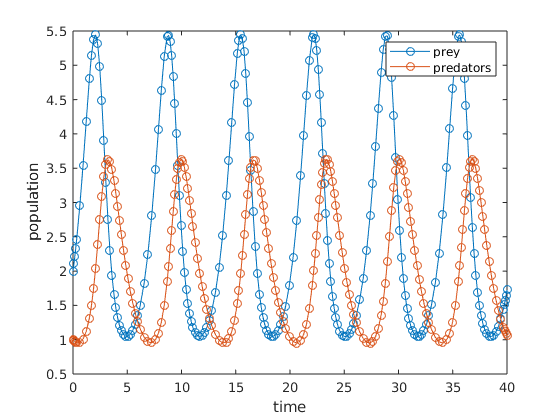


[ts, ys] = ode45(fcn,[t0, 40],y0);
figure
plot(ts,ys,'o-')
legend('prey', 'predators')
xlabel('time')
ylabel('population')